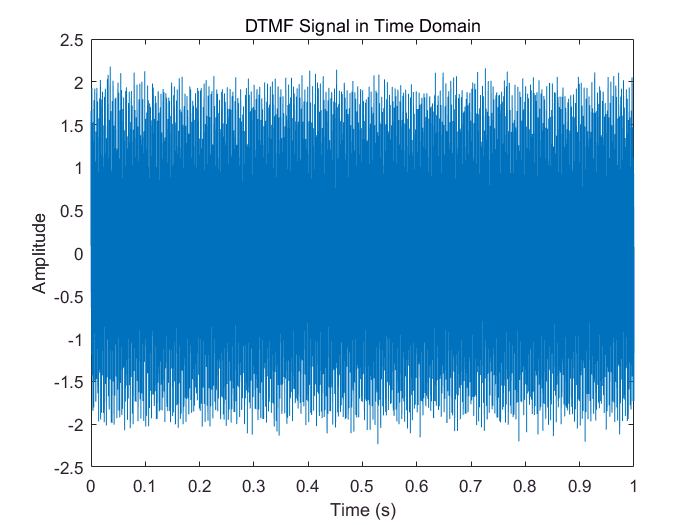

% DTMF 信号识别示例
clear; clc;

% 参数设置
fs = 8000; % 采样频率
t = 0:1/fs:1; % 时间向量，持续 1 秒


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 输入可调
% 生成测试 DTMF 信号（例如按下 '5'）
f1 = 770; % 行频率
f2 = 1336; % 列频率
signal = sin(2*pi*f1*t) + sin(2*pi*f2*t); % DTMF 信号
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



% 添加噪声
noise = 0.1*randn(size(signal));
signal = signal + noise; 

% 绘制时间域信号
figure;
plot(t, signal);
title('DTMF Signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');


% 进行 FFT
N = length(signal);
Y = fft(signal);
P2 = abs(Y/N); % 双边振幅谱
P1 = P2(1:N/2+1); % 单边振幅谱

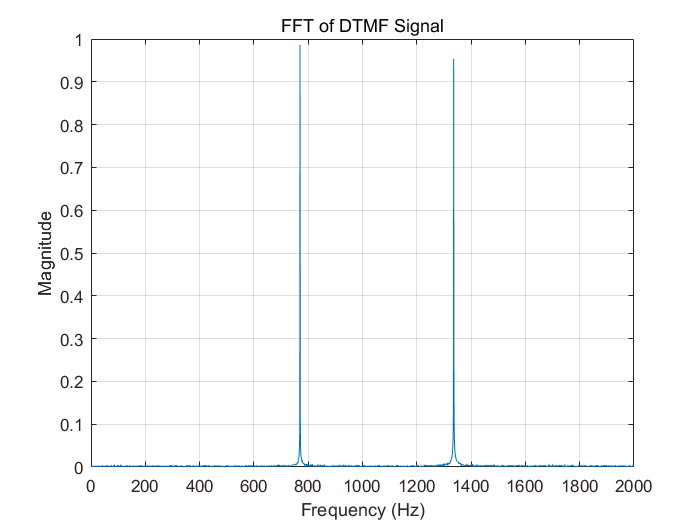

P1(2:end-1) = 2*P1(2:end-1); % 单边振幅谱修正
f = fs*(0:(N/2))/N; % 频率轴

% 绘制频域信号
figure;
plot(f, P1);
title('FFT of DTMF Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([0 2000]); % 限制到相关频率范围
grid on;


% 识别 DTMF 按键
threshold = 0.5; % 阈值设置
[peaks, locs] = findpeaks(P1, 'MinPeakHeight', threshold);
detected_freqs = int32(f(locs))

detected_freqs = 1×2 int32 行矢量
    770   1336



% 根据检测到的频率识别按键
key = identify_dtmf(detected_freqs)

key = '5'

disp(['Detected Key: ', key]);

Detected Key: 5
